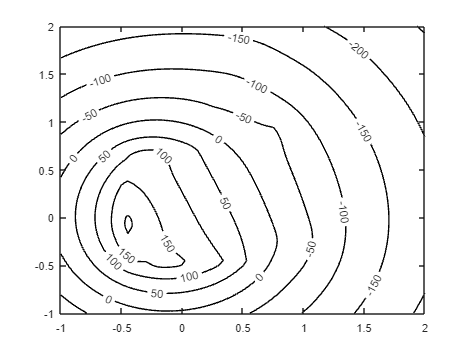

[x,y]=meshgrid(-1:0.05:2,-1:0.05:2); % define the potential at all mesh points

v = log(sqrt((x-0.244).^2+(y-1.128).^2)); % function that defines Bob as sink

global_points = globalCleaned; % global points from gauntlet map

i = 1;
while i < 244 % loop through all global points
    % define x, y coordinate pair
    x_coord = global_points(1,i);
    y_coord = global_points(2,i);
    v = build_equation(v, x, y, x_coord, y_coord); % add source at coordinate
    i = i + 1;
end

% plot contours with levels marked
contour(x,y,v,'k','ShowText','On')

function [v] = build_equation(v, x, y, x_coord, y_coord)
% Add new source to equation evaluted at meshgrid.
%
% Inputs
%   v (square matrix): Equation evaluted at meshgrid
%   x (square matrix): X coordinates of meshgrid
%   y (square matric): Y coordinates of meshgrid
%   x_coord (float): X coordinate of source
%   y_coord(float): Y coordinate of source
%
% Returns
%   v (square matrix): Newly built equation evaluted at meshgrid

    v = v - (log(sqrt((x-x_coord).^2+(y-y_coord).^2)));
end